c =  0.055 %in m, mean aerodynamic chord

c = 0.0550

eta = [linspace(0,0.0025,10) linspace(0.0025,0.02,15) linspace(0.02,0.3,60) linspace(0.3,1,40)]

eta =          0    0.0003    0.0006    0.0008    0.0011    0.0014    0.0017    0.0019    0.0022    0.0025    0.0025    0.0037    0.0050    0.0063    0.0075    0.0088    0.0100    0.0113    0.0125    0.0138    0.0150    0.0163    0.0175    0.0188    0.0200    0.0200    0.0247    0.0295    0.0342    0.0390    0.0437    0.0485    0.0532    0.0580    0.0627    0.0675    0.0722    0.0769    0.0817    0.0864    0.0912    0.0959    0.1007    0.1054    0.1102    0.1149    0.1197    0.1244    0.1292    0.1339


%eta = [0:0.005:0.4 0.4:0.01:0.8 0.8:0.05:1]
%%%%%%%%%%%%%%%
zc_max = 0.18/(1 + 7.31*(0.4)^2.77) %zc_max/c

zc_max = 0.1141

zt_max = 0.1/(1 + 14.86*(0.4)^3.52) %zt_max/c

zt_max = 0.0629

%%%%%%%%%%%%%%%
S1 = 3.9362;
S2 = -0.7705;
S3 = 0.8485;
A1 = -29.486;
A2 = 66.4565;
A3 = -59.8060;
A4 = 19.0439;
%%%%%%%%%%%%%%%
a = 2.*eta - 1

a =    -1.0000   -0.9994   -0.9989   -0.9983   -0.9978   -0.9972   -0.9967   -0.9961   -0.9956   -0.9950   -0.9950   -0.9925   -0.9900   -0.9875   -0.9850   -0.9825   -0.9800   -0.9775   -0.9750   -0.9725   -0.9700   -0.9675   -0.9650   -0.9625   -0.9600   -0.9600   -0.9505   -0.9410   -0.9315   -0.9220   -0.9125   -0.9031   -0.8936   -0.8841   -0.8746   -0.8651   -0.8556   -0.8461   -0.8366   -0.8271   -0.8176   -0.8081   -0.7986   -0.7892   -0.7797   -0.7702   -0.7607   -0.7512   -0.7417   -0.7322


zc = zc_max.*eta.*(1-eta).*(S1 + S2.*a + S3.*(a.^2))

zc =          0    0.0002    0.0004    0.0005    0.0007    0.0009    0.0011    0.0012    0.0014    0.0016    0.0016    0.0024    0.0031    0.0039    0.0047    0.0055    0.0062    0.0070    0.0077    0.0085    0.0092    0.0100    0.0107    0.0115    0.0122    0.0122    0.0150    0.0177    0.0203    0.0229    0.0255    0.0280    0.0305    0.0329    0.0353    0.0376    0.0399    0.0421    0.0443    0.0464    0.0485    0.0506    0.0526    0.0546    0.0565    0.0584    0.0603    0.0621    0.0638    0.0656


zt = zt_max.*(A1.*(eta.^2 - eta.^0.5) + A2.*(eta.^3 - eta.^0.5) ...
    + A3.*(eta.^4 - eta.^0.5) + A4.*(eta.^5 - eta.^0.5))

zt =          0    0.0040    0.0056    0.0069    0.0079    0.0089    0.0097    0.0105    0.0112    0.0119    0.0119    0.0146    0.0168    0.0188    0.0205    0.0222    0.0237    0.0251    0.0264    0.0276    0.0288    0.0299    0.0310    0.0320    0.0330    0.0330    0.0364    0.0394    0.0421    0.0445    0.0466    0.0486    0.0503    0.0519    0.0534    0.0547    0.0559    0.0569    0.0579    0.0587    0.0595    0.0602    0.0607    0.0612    0.0617    0.0620    0.0623    0.0626    0.0627    0.0629


%%%%%%%%%%%%%%%%%
zu = zc+zt

zu =          0    0.0041    0.0060    0.0074    0.0086    0.0098    0.0108    0.0117    0.0126    0.0135    0.0135    0.0169    0.0199    0.0227    0.0252    0.0276    0.0299    0.0320    0.0341    0.0361    0.0380    0.0399    0.0417    0.0435    0.0452    0.0452    0.0514    0.0571    0.0624    0.0674    0.0721    0.0766    0.0808    0.0848    0.0886    0.0923    0.0957    0.0990    0.1022    0.1052    0.1080    0.1107    0.1133    0.1158    0.1182    0.1204    0.1226    0.1246    0.1266    0.1284


zl = zc-zt

zl =          0   -0.0038   -0.0053   -0.0064   -0.0072   -0.0080   -0.0087   -0.0093   -0.0098   -0.0103   -0.0103   -0.0122   -0.0137   -0.0149   -0.0159   -0.0167   -0.0174   -0.0181   -0.0186   -0.0191   -0.0196   -0.0199   -0.0203   -0.0205   -0.0208   -0.0208   -0.0215   -0.0218   -0.0218   -0.0215   -0.0211   -0.0206   -0.0199   -0.0190   -0.0181   -0.0171   -0.0160   -0.0148   -0.0136   -0.0123   -0.0109   -0.0096   -0.0081   -0.0067   -0.0052   -0.0036   -0.0021   -0.0005    0.0011    0.0027


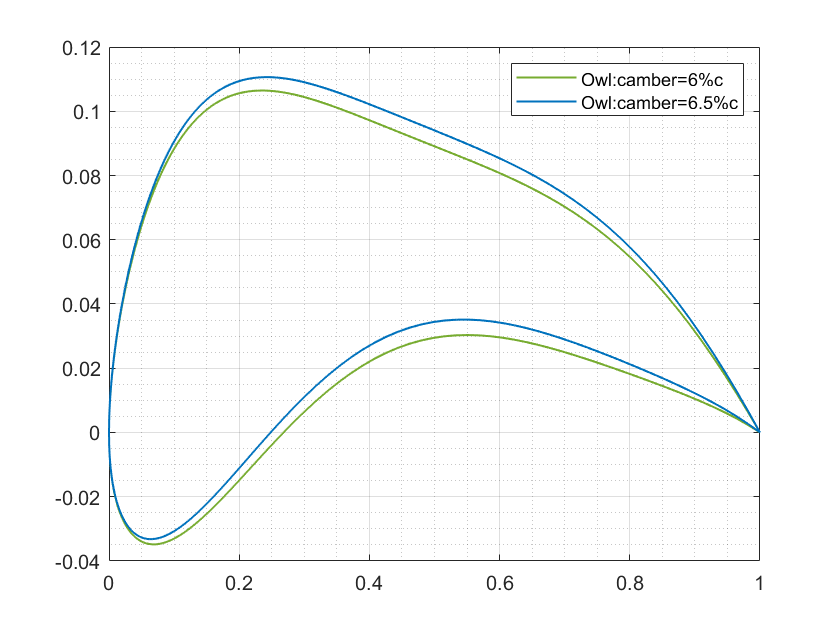

%%%%%%%%%%%%%%%%%%\

plot(owl_6c(:,1), owl_6c(:,2),'Color','#77AC30','LineWidth',1 )
hold on
plot(owl_6_5c(:,1), owl_6_5c(:,2),'Color','#0072BD','LineWidth',1 )
legend('Owl:camber=6%c','Owl:camber=6.5%c')
grid on
grid minor
hold off

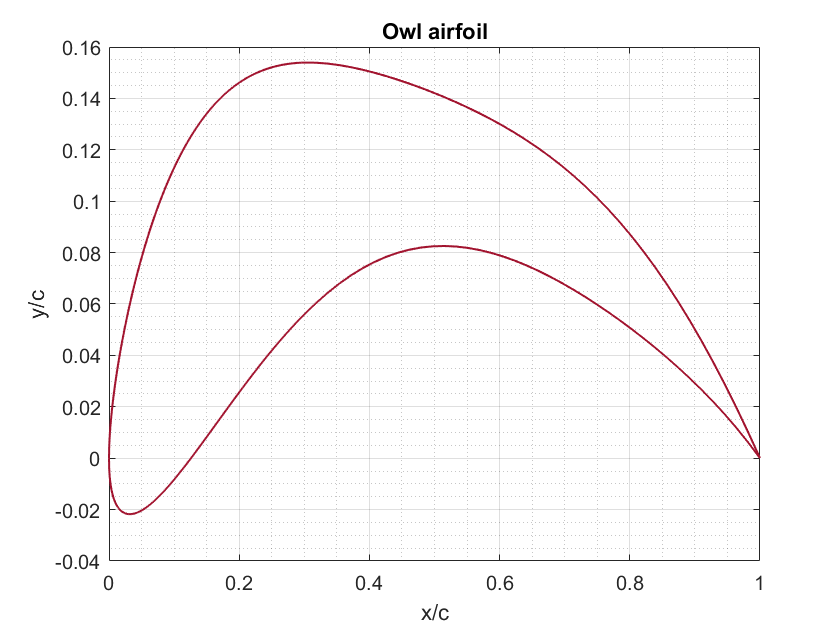

plot(eta,zu,'Color','#A2142F','LineWidth',1)
hold on
plot(eta,zl,'Color','#A2142F','LineWidth',1)
title('Owl airfoil')
%plot(eta, zc)
xlabel('x/c')
ylabel('y/c')
ylim([-0.04 0.16])
grid on
grid minor